# Hankel Matrix Completion

## Experimenting with LTI's without input

First we get an intuition of state space definition without input. We deal with discrete systems, since we are interested in data sampled at specific time points in history.

% statenum states, outputnum outputs, 0 input
statenum = 100;
outputnum = 1;

state_space = drss(statenum,outputnum,0)

state_space =
 
  A = 
                 x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48         x49         x50         x51         x52         x53         x54         x55         x56         x57         x58         x59         x60         x61         x62         x63         x64         x65         x66         x67         x68         x69         x70         x71         x72         x73         x74         x75         x76         x77         x78         x79         x80         x

dssprop(state_space)

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 0"
    "Number of outputs: 1"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:0"  
    "C_rows:1"      "C_cols:100"
    "D_rows:1"      "D_cols:0"  

Max absolute eigen value: 1
Eigen values of A: 
    0.9456
    0.9456
    0.9913
    0.8331
    0.8331
    0.8461
    0.7929
    0.7929
    0.7099
    0.7099
    0.8028
    0.7727
    0.9333
    0.9333
    0.7360
    0.7537
    0.7537
    0.7205
    0.7146
    0.9647
    0.9647
    0.9278
    0.9278
    0.6880
    0.6880
    0.9511
    0.9363
    0.9270
    0.5387
    0.5387
    0.4962
    0.4962
    0.8521
    0.8423
    0.5588
    0.5584
    0.7462
    0.7920
    0.7928
    0.6670
    0.4660
    1.0000
    1.0000
    1.0000
    0.3804
    0.3804
    0.5777
    0.8532
    0.8532
    0.3766
    0.3766
    0.5488
    0.4527
    0.4527
    0.3499
    0.4619
    0.2830
    0.2830
    0.2717
    0.3115
    0.3115
    0.3766
    0

Now we create a set of outputs, with x(0) = x_0 != 0 (since we dont have an input and thus if the state is the zero vector the transfer function will not do anything to the state)

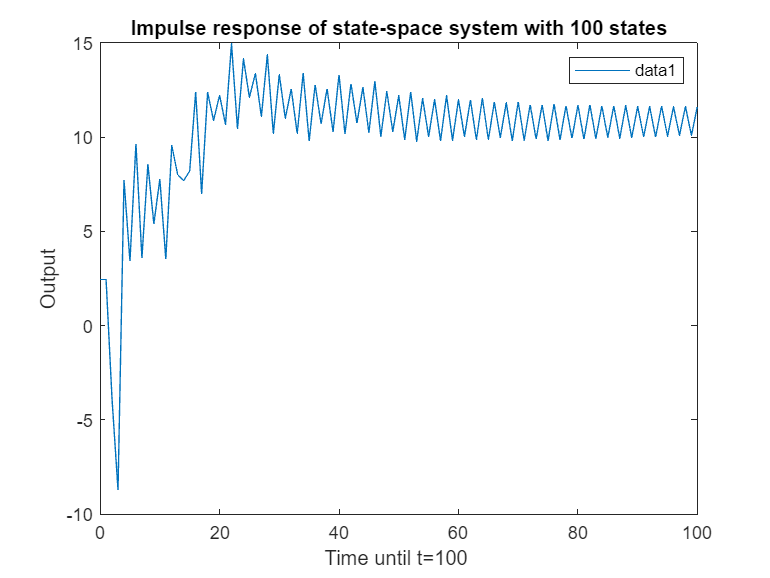

maxTime = 100;

figure;
dssplot(state_space,maxTime);

Notice that its possible for one of the eigenvalues to be exactly 1, which is neither stable nor unstable (marginally stable). Using the drss function we can generate many different kinds of discrete-time state-space systems that are stable. In the plot we observe that after a large enough T the impulse response stabilizes.

## Experimenting with LTI's with input

We can also generate an LTI with an input vector upon which a transformation B and D have an effect on the state change and output. We can have a single-input or multi-input.

% statenum states, outputnum outputs, inputnum input
statenum = 100;
outputnum = 4;
inputnum = 4;
maxTime = 100;
input = [2;1;2;3];


state_space = drss(statenum,outputnum,inputnum)

state_space =
 
  A = 
                 x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48         x49         x50         x51         x52         x53         x54         x55         x56         x57         x58         x59         x60         x61         x62         x63         x64         x65         x66         x67         x68         x69         x70         x71         x72         x73         x74         x75         x76         x77         x78         x79         x80         x

dssprop(state_space)

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 4"
    "Number of outputs: 4"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:4"  
    "C_rows:4"      "C_cols:100"
    "D_rows:4"      "D_cols:4"  

Max absolute eigen value: 1
Eigen values of A: 
    0.9619
    0.9619
    0.9186
    0.9186
    0.8986
    0.8986
    0.7127
    0.7127
    0.7018
    0.7018
    1.0000
    0.9806
    0.9378
    0.9235
    0.9111
    0.9938
    0.9938
    0.8974
    0.8974
    0.8665
    0.8535
    0.8747
    0.8747
    0.9080
    0.8269
    0.8269
    0.8848
    0.8247
    0.6500
    0.6500
    0.7728
    0.8473
    0.6612
    0.6612
    0.7138
    0.5207
    0.5207
    0.6203
    0.7151
    0.7151
    0.6848
    0.5994
    0.5994
    0.6640
    0.5916
    0.6537
    0.6369
    0.6400
    0.5562
    0.5383
    0.3673
    0.3673
    0.5173
    0.5454
    0.4966
    0.5011
    0.5011
    0.4985
    0.5410
    0.3011
    0.3011
    0.3276
    0

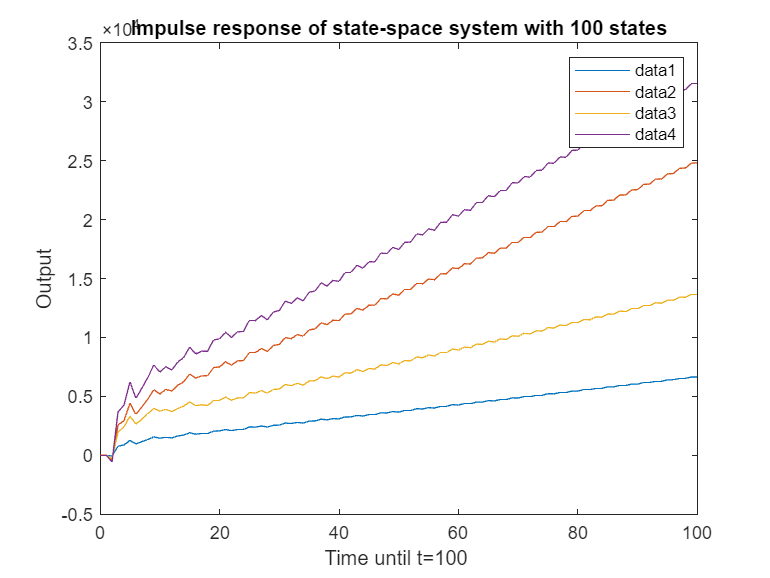

figure;
dssplot(state_space,maxTime,input);

Lets plot the trajectory of the impulse response with the old input and some new input.

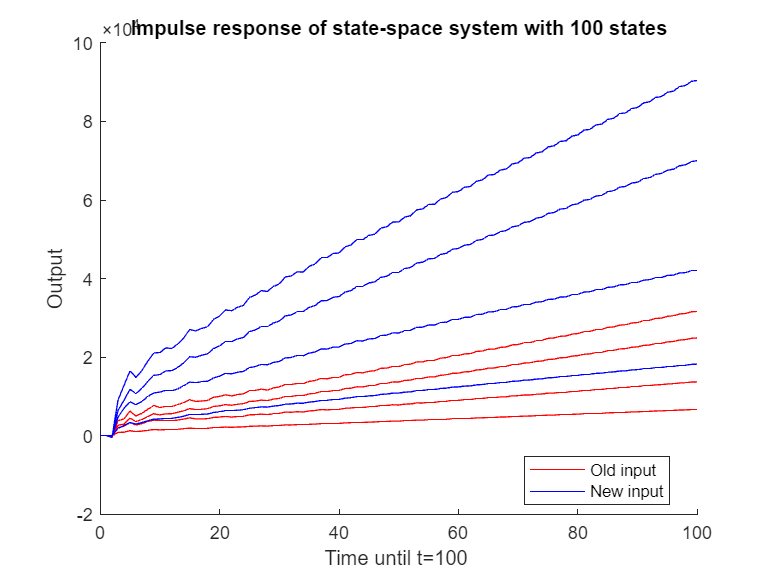

figure;
hold on
f1 = dssplot(state_space,maxTime,input);
f2 = dssplot(state_space,maxTime,[2;1;5;6]);
set(f1, 'Color', 'r');
set(f2, 'Color', 'b');
legend([f1(1), f2(1)], {'Old input', 'New input'}, 'Location', 'best');
hold off;

## Experimenting with Hankel Matrices

Now we're going to experiment with hankel matrices and show how it is relevant to time-series data.  Firstly, we create a drss and with a single in- and output and random initial conditions. We then convert the output to a hankel matrix.

input = 2;
inputnum = 1;
outputnum = 1; 
statenum = 3;
maxTime = 50;

dss = drss(statenum, outputnum, inputnum)

dss =
 
  A = 
            x1       x2       x3
   x1    0.521   0.0067   -0.609
   x2    0.566   0.1634   -1.269
   x3  -0.2971   0.3695   0.4072
 
  B = 
         u1
   x1     0
   x2     0
   x3  1.83
 
  C = 
          x1     x2     x3
   y1      0  2.354  1.706
 
  D = 
       u1
   y1   0
 
Sample time: unspecified
Discrete-time state-space model.


[x,y] = dsssim(dss,maxTime,input)

x =     0.1456    0.0730   -2.3498   -4.4901   -5.2655   -5.0230   -4.5191   -4.2216   -4.1935   -4.2936   -4.3845   -4.4154   -4.4026   -4.3797   -4.3668   -4.3661   -4.3707   -4.3747   -4.3760   -4.3754   -4.3743   -4.3738   -4.3738   -4.3740   -4.3742   -4.3742   -4.3742   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741   -4.3741
    0.8146    0.1982   -4.9044   -8.8679   -9.9639   -9.2195   -8.1843   -7.6715   -7.6908   -7.9170   -8.0883   -8.1310   -8.0945   -8.0481   -8.0263   -8.0281   -8.0385   -8.0460   -8.0476   -8.0459   -8.0438   -8.0429   -8.0430   -8.0435   -8.0438   -8.0439   -8.0438   -8.0437   -8.0436   -8.0436   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8.0437   -8

y =     1.9406    1.9406    7.1571   -2.4890  -12.8433  -17.2537  -16.5452  -14.1874  -12.6153  -12.3398  -12.7678  -13.2202  -13.4027  -13.3615  -13.2539  -13.1855  -13.1756  -13.1958  -13.2159  -13.2235  -13.2213  -13.2164  -13.2135  -13.2131  -13.2141  -13.2150  -13.2153  -13.2152  -13.2150  -13.2148  -13.2148  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149


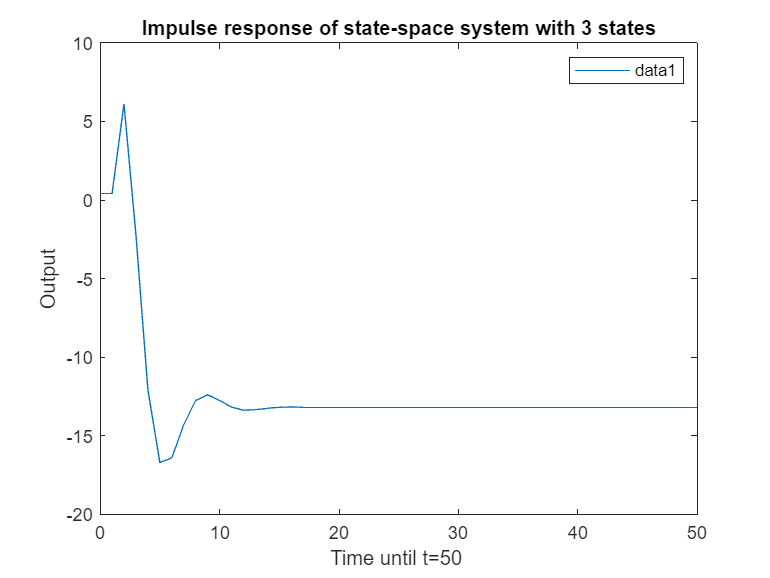

dssplot(dss,maxTime,input);

delta = 26

delta = 26

c = y(1,1:delta)

c =     1.9406    1.9406    7.1571   -2.4890  -12.8433  -17.2537  -16.5452  -14.1874  -12.6153  -12.3398  -12.7678  -13.2202  -13.4027  -13.3615  -13.2539  -13.1855  -13.1756  -13.1958  -13.2159  -13.2235  -13.2213  -13.2164  -13.2135  -13.2131  -13.2141  -13.2150


r =y(1,delta:size(y,2))

r =   -13.2150  -13.2153  -13.2152  -13.2150  -13.2148  -13.2148  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149  -13.2149


H = hankel(c,r)

H =     1.9406    1.9406    7.1571   -2.4890  -12.8433  -17.2537  -16.5452  -14.1874  -12.6153  -12.3398  -12.7678  -13.2202  -13.4027  -13.3615  -13.2539  -13.1855  -13.1756  -13.1958  -13.2159  -13.2235  -13.2213  -13.2164  -13.2135  -13.2131  -13.2141  -13.2150
    1.9406    7.1571   -2.4890  -12.8433  -17.2537  -16.5452  -14.1874  -12.6153  -12.3398  -12.7678  -13.2202  -13.4027  -13.3615  -13.2539  -13.1855  -13.1756  -13.1958  -13.2159  -13.2235  -13.2213  -13.2164  -13.2135  -13.2131  -13.2141  -13.2150  -13.2153
    7.1571   -2.4890  -12.8433  -17.2537  -16.5452  -14.1874  -12.6153  -12.3398  -12.7678  -13.2202  -13.4027  -13.3615  -13.2539  -13.1855  -13.1756  -13.1958  -13.2159  -13.2235  -13.2213  -13.2164  -13.2135  -13.2131  -13.2141  -13.2150  -13.2153  -13.2152
   -2.4890  -12.8433  -17.2537  -16.5452  -14.1874  -12.6153  -12.3398  -12.7678  -13.2202  -13.4027  -13.3615  -13.2539  -13.1855  -13.1756  -13.1958  -13.2159  -13.2235  -13.2213  -13.2164  -13.2135  -13.2131  -

rank(H)

ans = 5

## Experimenting with Hankel Matrix Completion